clear all
close all
clc

%%% plotting script for the reviewer

## Load all the data

disp('Loading data...');

Loading data...


load('FinalData/Reviewer_Data_R2.mat');
disp('Data laoded!')

Data laoded!


## Select which data to plot

BacteriaCases = {'EC_RI','EC_NA','BAC_PA'};
WaitTime = {'H0','H1','H2','H3','H4','H24'};
BacteriaCaseNum = 2;
WaitTimeNum = 6;

## Extract data for the selected case

HoloIm = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).Holo;
Fluoro = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).Fluor;
InvPhase = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).InvPhase;
CellWall = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).CellWall;
Skeleton = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).Skeleton;
FContrastScale = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).FContrastScale;
InvPhaseContrastScale = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).InvPhaseContrastScale;
CWallColor = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).CWallColor;
SkelColor = PlotData.(BacteriaCases{BacteriaCaseNum}).(WaitTime{WaitTimeNum}).SkelColor;


## Extract intensity profiles along the skeleton

% Find endpoints of the skeleton (pixels with only one neighbor)
PhaseSkelEndPoints = bwmorph(Skeleton, 'endpoints');
[PhaseEndPointsY, PhaseEndPointsX] = find(PhaseSkelEndPoints);

% Choose one endpoint as the starting point
PhaseStartPoint = [PhaseEndPointsY(1), PhaseEndPointsX(1)];

%%- Order the Skeleton Coordinates
% Get coordinates of all skeleton pixels
[PhaseSkelY, PhaseSkelX] = find(Skeleton);

% Use bwdistgeodesic to compute geodesic distances along the skeleton
DistancePhase = bwdistgeodesic(Skeleton, PhaseStartPoint(1), PhaseStartPoint(2));

% Extract distances for the skeleton pixels
PhaseDVals = DistancePhase(sub2ind(size(DistancePhase), PhaseSkelY, PhaseSkelX));

% Sort the skeleton pixels based on the geodesic distance from the start
[~, PhaseSortIdx] = sort(PhaseDVals);
PhaseOrderedCoords = [PhaseSkelY(PhaseSortIdx), PhaseSkelX(PhaseSortIdx)];

% Compute cumulative distance along the ordered coordinates
PhaseDelta = diff(PhaseOrderedCoords);
PhaseCumDist = [0; cumsum(sqrt(sum(PhaseDelta.^2, 2)))];
% Normalize the distance to the range [0,1]
PhaseNormDist = PhaseCumDist/PhaseCumDist(end);

%%- Sample Intensity Values Along the Skeleton
% Use interp2 to sample intensities at the skeleton pixel locations.
% Note: interp2 requires (x,y) coordinates, where x corresponds to columns.
FluoroProfile = interp2(Fluoro, PhaseOrderedCoords(:,2), PhaseOrderedCoords(:,1), 'linear', 0);
InvPhaseProfile  = interp2(InvPhase, PhaseOrderedCoords(:,2), PhaseOrderedCoords(:,1), 'linear', 0);

## Set contrast scales and overlay the cell wall and the skeleton


%%% putting the cell wall in the image
FluoroImg = imoverlay(mat2gray(Fluoro,FContrastScale), CellWall, CWallColor);
InvPhaseImg = imoverlay(mat2gray(InvPhase,InvPhaseContrastScale), CellWall, CWallColor);

%%% putting the skeleon on the image
FluoroImg = imoverlay(FluoroImg, Skeleton, SkelColor);
InvPhaseImg = imoverlay(InvPhaseImg, Skeleton, SkelColor);

## Plot

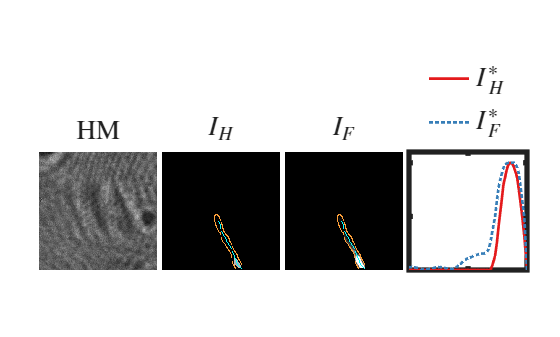

figure;
subplot(1,4,1)
imshow(HoloIm)
title('HM','Interpreter','latex','FontSize',20)
subplot(1,4,2)
imshow(InvPhaseImg)
title('$I_H$','Interpreter','latex','FontSize',20)
subplot(1,4,3)
imshow(FluoroImg)
title('$I_F$','Interpreter','latex','FontSize',20)
subplot(1,4,4)
x1 = (PhaseNormDist);
y1 = (smooth(FluoroProfile));
x2 = (PhaseNormDist);
y2 =  (smooth(InvPhaseProfile));
x1 = rescale(x1);
y1 = rescale(y1);
x2 = rescale(x2);
y2 = rescale(y2);
plot(rescale(x2),rescale(smooth(y2)),'LineWidth',2); hold on;
plot(rescale(x1),rescale(smooth(y1)),'LineWidth',2,'LineStyle',':'); hold on;
% plot(PhaseNormDist,InvPhaseProfile,'LineWidth',2); hold on;
% plot(PhaseNormDist,FluoroProfile,'LineWidth',2); hold on;
ax = gca; ax.LineWidth = 4;
ax.YAxisLocation = 'right';
ax.FontSize = 24;
xticklabels([])
yticklabels([])
legend({'$I^{*}_{H}$', '$I^{*}_{F}$'}, 'Location', 'northoutside','Box','off','Interpreter','latex','FontSize',20);%,'Position',[0.195402018229167,0.895663440833258,0.037320963541667,0.056766055045871]);
axis square
ylim([0,1.1])
xlim([0,1])

ha = get(gcf,'children');
NumHandles = length(ha);

ha(NumHandles - 0).Position = [0,0.2,0.35,0.35];
ha(NumHandles - 1).Position = [0.22,0.2,0.35,0.35];
ha(NumHandles - 2).Position = [0.44,0.2,0.35,0.35];
ha(NumHandles - 3).Position = [0.66,0.2,0.35,0.35];